% eeglab's EEG structure and indexing
% mikeXcohen@gmail.com

## load in EEG data

load sampleEEGdata.mat

% FYI, this would also work:
% [file2load,path4file]=uigetfile('*.mat','Please select EEG data file');
% load([ path4file file2load ])

% take a minute to inspect the EEG structure
EEG

EEG = struct with fields:
             setname: 'EEG sample dataset'
            filename: ''
            filepath: ''
             subject: ''
               group: ''
           condition: ''
             session: []
            comments: [4×63 char]
              nbchan: 64
              trials: 99
                pnts: 640
               srate: 256
                xmin: -1
                xmax: 1.4961
               times: [1×640 double]
                data: [64×640×99 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×64 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: [-67 -68]
               event: [1×311 struct]
             urevent: [1×3009 struct]
    eventdescription: {''  ''  ''  ''  ''}
               epoch: [1×99 struct]
    epochdescription: {}
              reject: [1×1 struct]
               stats: [1×1 struct]
           

## finding time indices based on ms

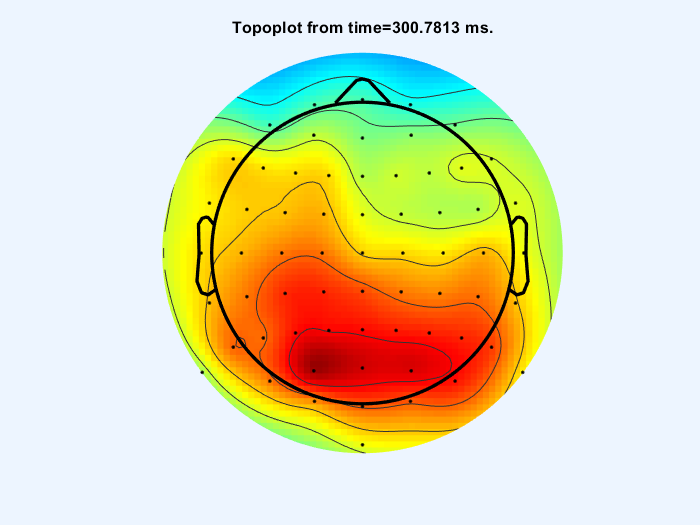

% The problem: We want to create a topographical plot at time=300 ms

time2plot = 300; % in ms!

[minval, minidx] = min(abs(EEG.times-time2plot)); 
%讓timepoint 300作為index，而非第300個timepoint

% extract the trial-averaged data from requested time point
% (note: this code contains an error!)
data2plot = squeeze(mean( EEG.data(:,minidx,:) ,3));


% plot
figure(1), clf
topoplot(data2plot,EEG.chanlocs);
title([ 'Topoplot from time=' num2str(EEG.times(minidx)) ' ms.' ])

## same concept for frequencies

frex = linspace(2,100,42);

freqIwant = 23; % in hz

% use min(abs trick to find closest frequency to 23 Hz
[~,frexidx] = min(abs(frex-freqIwant));

% the function dsearchn also works
frexidx = dsearchn(frex',freqIwant);

## indexing channels based on names

% the electrode label that we want to analyze
electrodeName = 'p1'; % case doesn't matter

% find the channel number that corresponds to this label
electrodeidx = strcmpi(electrodeName,{EEG.chanlocs.labels});

% confirm that this electrode is correct
EEG.chanlocs(electrodeidx)

ans = struct with fields:
        labels: 'P1'
         theta: -156.5070
        radius: 0.2790
             X: -59.9127
             Y: 26.0421
             Z: 54.3808
     sph_theta: 156.5070
       sph_phi: 39.7750
    sph_radius: 85
          type: []
        urchan: 20


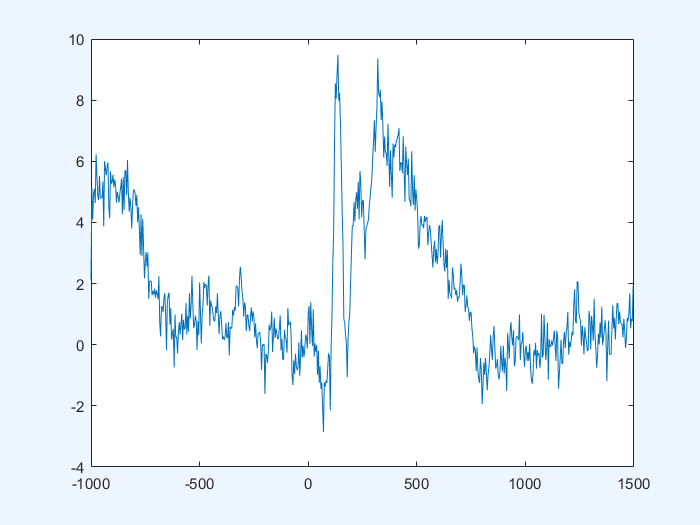


% plot the ERP from this electrode
figure(1), clf
plot(EEG.times,mean( EEG.data(electrodeidx,:,:),3 ))

## now multiple electrodes

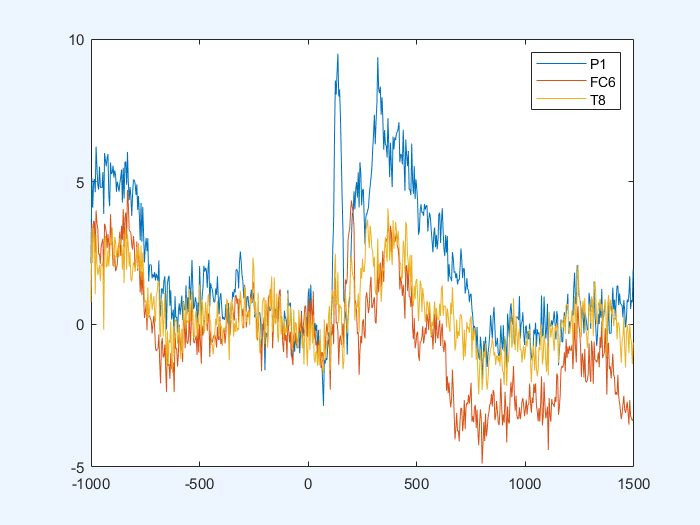

electrodeNames = {'p1';'fc6';'t8'};

% initialize
electrodeidx = zeros(size(electrodeNames));

% loop through electrodes and find the index of each one
% (The code below has three errors. Try to find/fix them!)
for chani=1:length(electrodeNames)
    try
        electrodeidx(chani) = find(strcmpi(electrodeNames{chani},{EEG.chanlocs.labels}));
    catch ME
        error('Something wrong with eletrode labeling')
    end
    
end
%electrodeNames{condi}對每個iteration都做一次string compare
%find(strcmpi(~))只找出不為0的那項element的位置 (因為1 by 1 != 1 by 64)

% plot all the ERPs
plot(EEG.times,mean( EEG.data(electrodeidx,:,:),3 ))
legend({EEG.chanlocs(electrodeidx).labels})